# **Generative AI Fundamentals**

[⇦ Main Menu](matlab:open('..\MainMenu.mlx'))

In this script, we provide an introduction to artificial intelligence (AI), focusing on generative and agentic processes. We then explore the underlying technology, large language models (LLMs), and demonstrate how to access them in MATLAB.

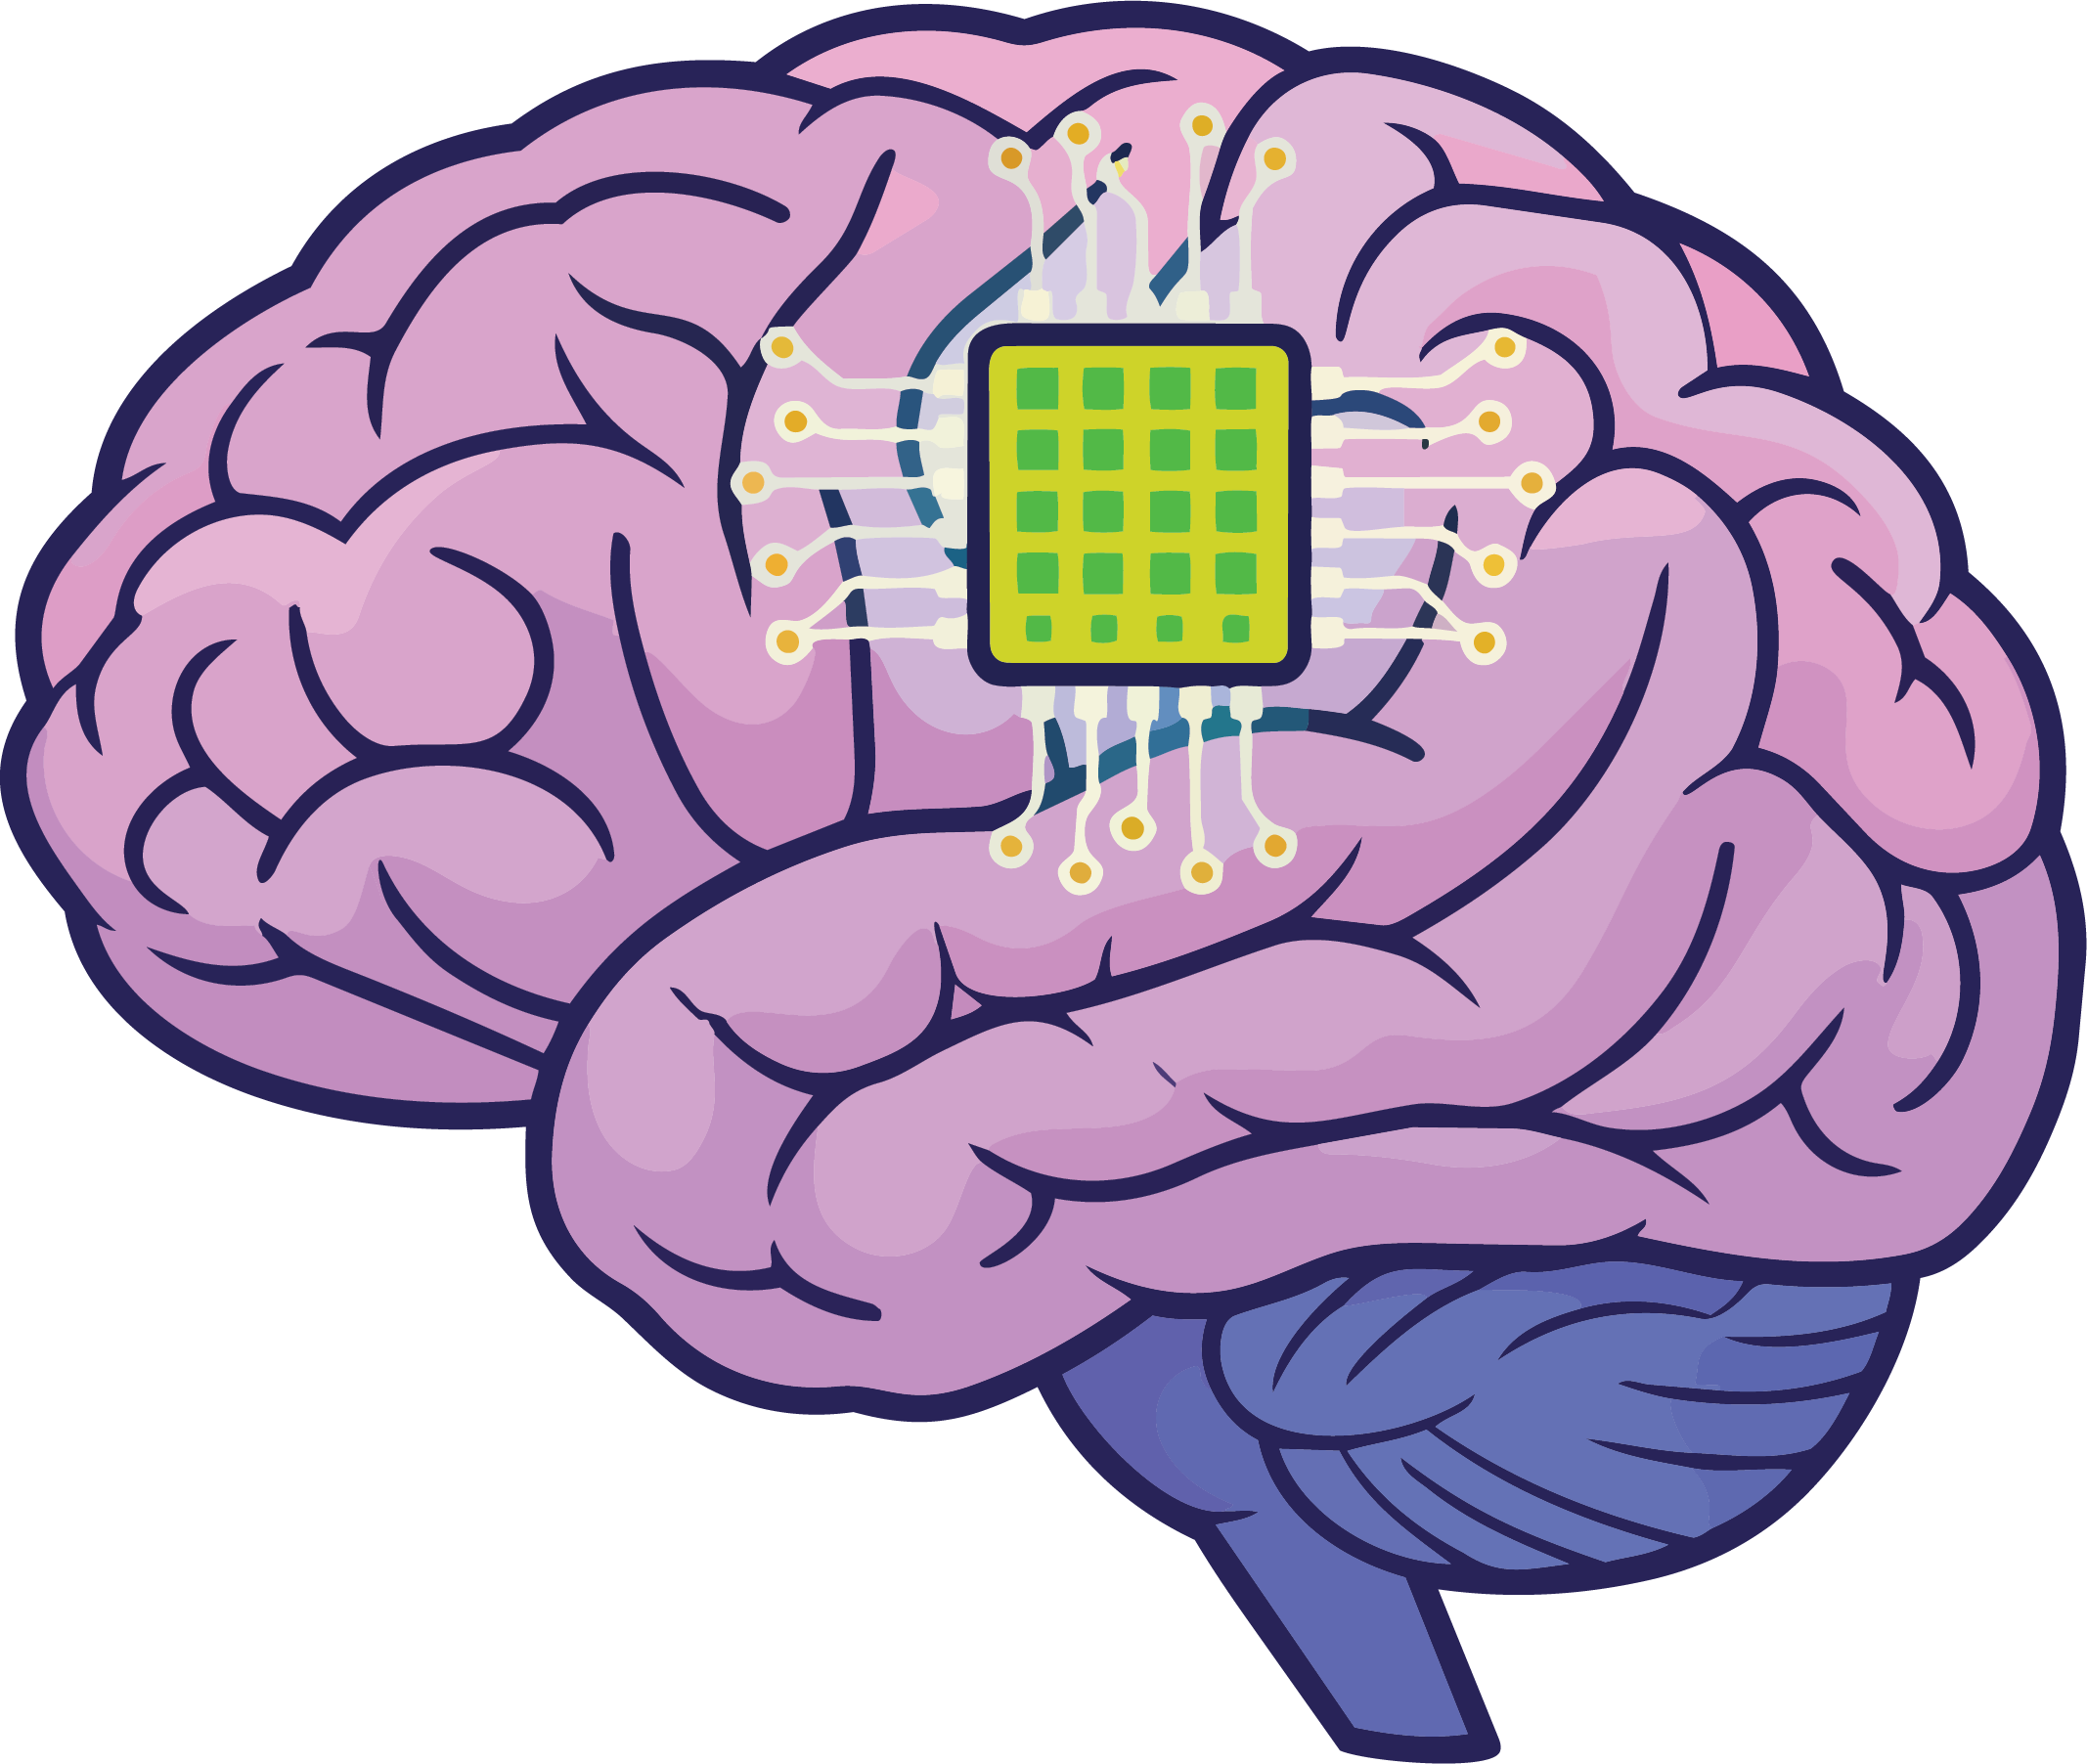

Created with Adobe Firefly

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction to Generative AI

Generative AI (GenAI) models are a class of artificial intelligence systems that generate new content such as text, images, music, code, and video. This is achieved by learning patterns from large amounts of existing data. Many GenAI models used for text-based tasks are powered by large language models (LLMs), which are trained on vast collections of text from sources such as books, websites, code, and conversations. During training, these learned patterns are encoded in the model’s parameters. An LLM is a specialized type of GenAI model designed to understand, generate, and process human language, making it an essential component behind many text‑based GenAI capabilities. AI Chatbots are a common application layer through which users interact with GenAI models and LLMs. The following image illustrates this hierarchy from application to model level.

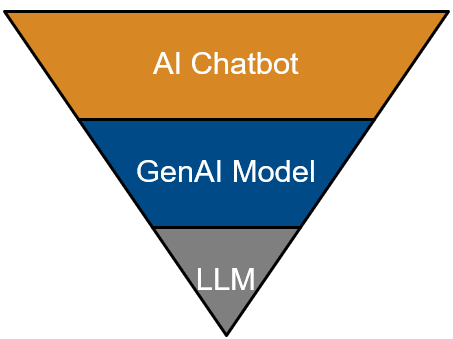

You've likely already used AI Chatbots like OpenAI's ChatGPT™, Microsoft Copilot™, Google Gemini, or Anthropic's Claude™. Each of these Chatbots can interact with their own various LLMs (e.g. ChatGPT with GPT-3.5, GPT-4, etc.). LLMs vary based on speed, accuracy, creativity, and capability for complex reasoning. GenAI is only the first step into the possibilities of current forms of AI. Consider some of the other types of AI that may occupy this space and how they compare to GenAI:

Agentic AI builds on generative AI by adding autonomy, planning, and action, using LLMs to pursue goals and shifting AI agents from reactive to proactive actions.

 **Exercise 1.** I have a variety of AI options at my disposal and want to use them to help me solve a problem. I want to autonomously book the cheapest nonstop flight from Boston to London next Friday, and returning on a Wednesday. I have a preference for aisle seats and want to use my airline miles for booking. In addition, I want to arrange transportation upon arrival and have the summarized options sent to my email. Which AI option would be best suited in creating this travel plan?

ExerciseSol1("Agentic AI");

### GenAI Literacy

GenAI literacy encompasses the skills and competencies needed to understand, evaluate, use, and ethically manage AI tools, including the LLMs on which they are based. Having GenAI as a useful skill requires understanding its capabilities and limitations. Another important skill for using GenAI is creating effective prompts.

#### Prompting

Using well-written prompts is key to producing the desired results from an LLM. They can range from being simple to very complex. They help to define the task, context, and constraints which help to determine the accuracy of the LLMs output. When writing a prompt, you should consider a few questions:

- What are the best practices for creating prompts?

- Did the prompt you created generated the results you expected?

- Should you trust the results? If not, how can you improve them?

#### Capabilities

GenAI provides a wide array of benefits in day-to-day tasks that can increase productivity or efficiency. Here are a few notable ones:

- Producing drafts (emails, papers, etc.)

- Summarizing (datasets, text, meeting notes)

- Creating content (images, videos)

- Writing code and debugging support

- Brainstorming ideas

 **Warning**. It should be stated with emphasis that you should **ALWAYS** validate the output of the LLM before using the information provided in your own work. For example, verifying sources of the information provided or validating that the code produced can be executed with no failures.

#### Limitations

While GenAI and LLMs can provide significant benefits, their underlying limitations make it essential to understand how and when to use them appropriately within a given context. For example, you could ask an LLM to compute the product of two numbers. You may get multiple and/or wrong answers. Why? Here are some reasons that could this could happen:

- Base LLMs are limited to knowledge from their training cutoff (Access to other software)

- LLMs will not give you the same output every time (Stochastic results)

- Outputs from LLMs may have mistakes or be completely false ([Hallucination](https://en.wikipedia.org/wiki/Hallucination_(artificial_intelligence)))

Additionally, there are other considerations regarding GenAI that may have societal impacts:

- Lack of diverse training data for LLMs can skew model outputs (Information Bias)

- Loss or leakage of personal information (Data privacy)

Let's look at an example of how using GenAI may have an impact on a situation:

 
displayFormula(["'You own an ice cream company that has attracted a lot of customers to its subscription program. '";"'The program promises two free cones a month as long as you remain subscribed. '";"'As a business owner, you want to find a way to leverage GenAI to make it easier to reach your subscriber base. '";"'You choose the free open source AI agent online and provide it with your customer data so that it can send emails on your behalf. '";"'The agent prioritized sending emails to those who have been subscribed the longest and not the newest subscribers. '";"'Not only did this streamline processes for the business but it reduced overhead as well.'"])

 **Exercise 2.** Based on the scenario from above, identify the following areas where GenAI may create concerns for your company. Please select all that apply and click the **Submit Answers** button below.

ExerciseSol2(...
    A = false, ...
    B = true, ...
    C = true, ...
    D = false);
 

### What is a tool?

Revisiting GenAI limitations, we have to take LLMs for what they are; a model that provides predictive text generation based on patterns. In other words, an LLM outputs text-based responses on what it is trained on. It may not be able to provide an accurate answer to a math problem that has multiple steps. This creates an opening for tools. Tools empower LLMs with more capabilities and access to data they may not be trained on. Typical AI agents use a combination of prompts and tools to direct an LLM toward a specific task. For example, MATLAB, is a tool that can provide enhanced computational and mathematical power to an LLM. 

#### Using an LLM for Tool Calling

Tool (or function) calling is a useful mechanism to provide greater access and power to an LLM. The LLM doesn't execute functions directly but outputs a structured response describing which tool or function to call and with what arguments. With the addition of a tool, like MATLAB, the LLM can be given instructions on how to call a function from MATLAB to perform a task. So when a prompt is submitted, the LLM decides which tool to call based on the problem. If it requires a MATLAB tool/function, it will execute that code and the LLM will return the output that MATLAB computed. The following diagram describes this process [1].

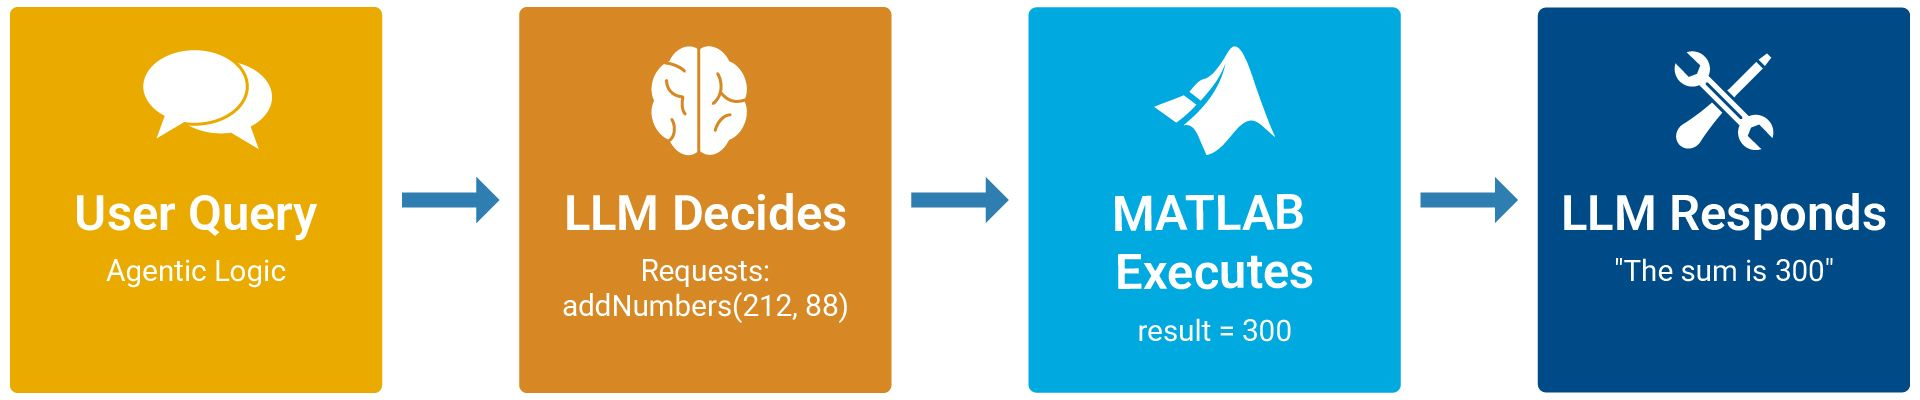

#### Using Model Context Protocol for Tool Calling

Imagine you have an AI agent to give you recommendations on clothes to wear based on the weather. The AI agent would need access to a tool such as a local weather data API to be accurate. To access different kinds of tools, an AI agent must be able to communicate over the model context protocol (MCP). You can think of MCP as the USB-C for AI, where the MCP creates a direct "wire" connection between the AI Agent and the tool. There are two ways to use MCP with MATLAB. The first is MATLAB as the tool, where you can have AI platforms execute MATLAB code ([MCP Core Server](https://www.mathworks.com/products/matlab-mcp-core-server.html)). 

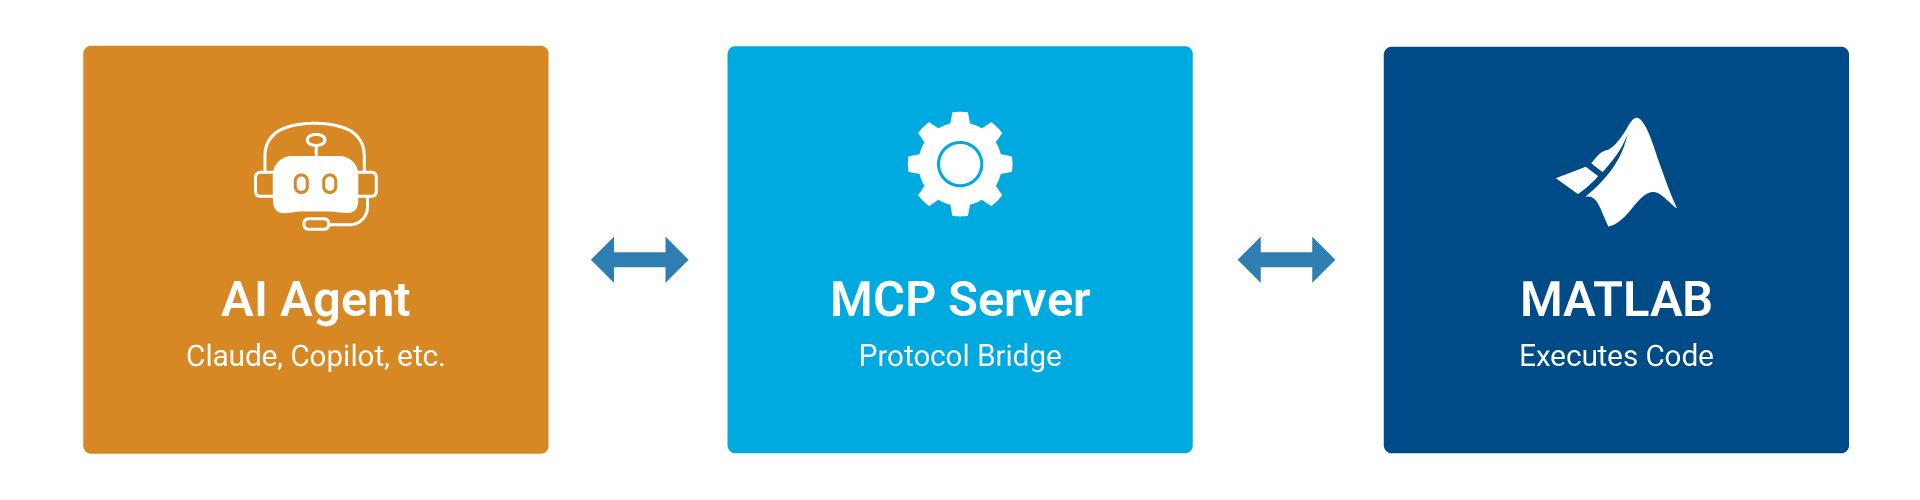

The second is MATLAB as the host, where you can build your own AI agent within MATLAB that can talk to external tools and APIs ([MCP Client](https://www.mathworks.com/matlabcentral/fileexchange/182699-matlab-mcp-http-client?s_tid=FX_rc2_behav)). 

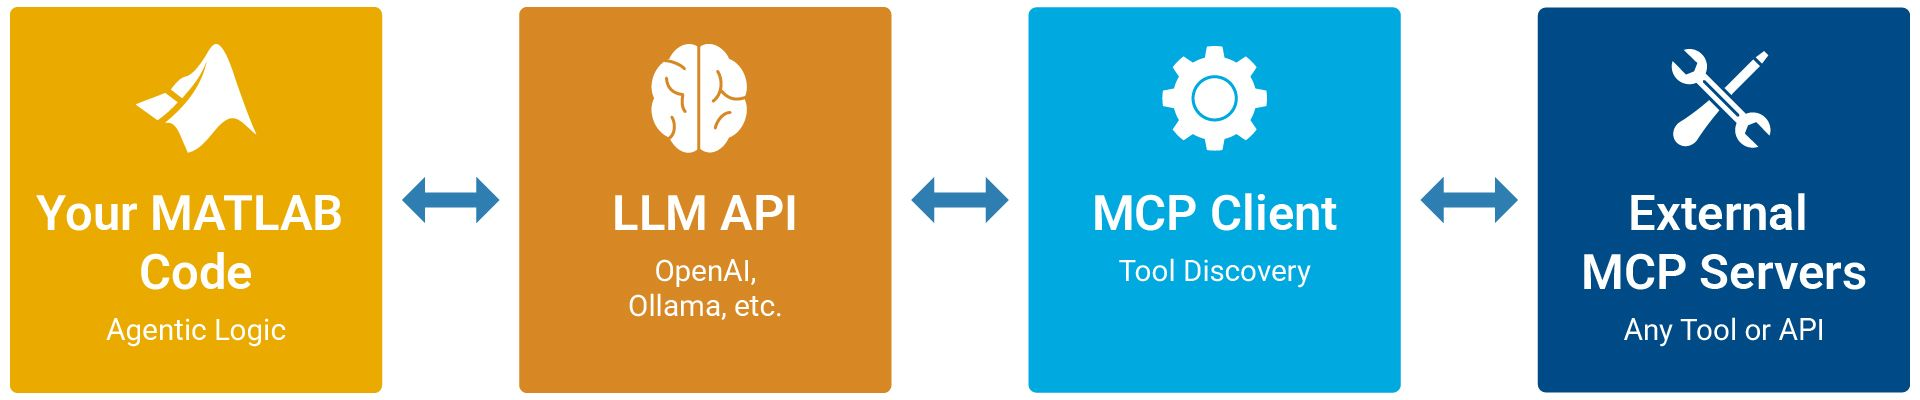

Revisiting the scenario of asking an LLM to compute the product of two numbers, if an LLM now has access to a tool like MATLAB, it can provide a more accurate and repeatable answer for the product. For more on using AI Agents with MATLAB through MCP or MATLAB connecting to 3rd party tools, check out the Further Exploration section.

## GenAI in the Context of Engineering

Engineering is a complex field that requires critical thinking and collaboration to produce safe and reliable products for the world to use. As people discover more applications of GenAI, it is being used in almost every field; especially in the areas of learning and problem-solving. However, that does not mean AI will replace good and responsible engineering. Rather, it is a resource for efficiency. Resources, such as GenAI can help to augment the processes we use to solve problems. It can assist in finding and addressing problems in a design earlier on, which benefits safety and cost. For example, let's say you are tasked with doing a numerical methods problem and you have to use the [Newton-Raphson method](https://en.wikipedia.org/wiki/Newton%27s_method) to solve the problem. If you have never heard of Newton's method, GenAI can help you in understand what it is, how it works, and finally how to use it. This can save time on the research about the numerical method and provide an iterative way of learning about different techniques. As a student, having instant feedback and learning support on a new topic creates an engaging environment and helps stimulate better questions.

## Using LLMs in MATLAB

There are a few AI-based software that MATLAB can access and talk to through its environment. Each of these software may provide access to a variety of LLMs to use. For this module, we will discuss two particular ways to interact with LLMs in MATLAB.

### Using a MATLAB Assistant

As of the 2025a release, MATLAB comes with an interactive coding assistant (or AI Chatbot) to help you perform coding tasks, [MATLAB Copilot](https://www.mathworks.com/products/matlab-copilot.html). The LLM it currently runs on is the GPT-5 mini model. This model may change as updates come along. You will learn more about Copilot in the next script, [IntroToCopilot.mlx](matlab:open('.\IntroToCopilot.mlx')).

### Using a 3rd Party LLM

As of the 2024a release, it is possible for users to connect some cloud-based and local LLMs to the MATLAB environment. This ultimately gives users:

- The ability to integrate some LLMs within MATLAB to automate workflows

- The ability to protect data by keeping sensitive information off of external servers (except in the case of cloud-based LLMs)

- The ability to create custom agentic workflows within MATLAB

 **Demonstration**. Let's create a custom AI agent to solve a problem. We will begin by asking an LLM directly to solve a problem. Then, we will ask the LLM to interact directly with MATLAB to solve the same problem. For this example, we will use the **Mistral NeMo** LLM running locally on **Ollama** from **MATLAB**. A sample prompt will be provided.

 **Note**. You will need to download a local version of the Ollama on your machine to perform this demonstration and exercises. You can download the platform and specific model following this process: [Model Install Process](matlab:open('..\Data\ModelInstallProcess.mlx'))

 **Warning**. Computation time may vary between machines for interacting with Ollama from MATLAB. The call to Ollama is set to time out after 4 minutes. If it does time out (error), you may use the slider below to increase the time limit and try running the prompt again.

tUpdate =4;

 

% Call local LLM and set timeout value to user input. 4 minutes is the default. 
if exist('tUpdate','var')
    Chat = ollamaChat("mistral-nemo","TimeOut",tUpdate*60)
else
    Chat = ollamaChat("mistral-nemo","TimeOut",240)
end

% Enter a prompt for the agent and time the operation (in minutes)
tic
LLM_Response = generate(Chat,"Can you show me the equation for solving a projectile motion problem?")
TotalT1 = toc;
FormatSpec1 = 'Total elapsed computation time is %.2g minutes\n';
fprintf(FormatSpec1,TotalT1/60);

 **Note**. Notice that Ollama’s response is still formatted as plain text, including any code that is associated with supporting the task. What would happen if we asked Ollama to use specific native MATLAB functions to perform this task?

This last prompt was helpful, but what if we want to use MATLAB to generate an equation that we can use for a coding project. Let's try an updated prompt.

 

% Update prompt for the agent to use a MATLAB toolbox and time the operation (in minutes)
tic
NewLLM_Response = generate(Chat,"Can you create code for solving a projectile motion problem using the symbolic toolbox?")
TotalT2 = toc;
FormatSpec2 = 'Total elapsed computation time is %.2g minutes\n';
fprintf(FormatSpec2,TotalT2/60);

  **Try**. Copy the updated code generated by Ollama into a live script and try to run it. Did it work? If yes, great! If not, revisit this note.

### Using an LLM with Tools

In the previous prompts, the LLM produced written code that could be ran to perform a task. However, what if we wanted a more specific role for the LLM where it could execute code to perform a task? This is where we can define specific MATLAB tools (or function calls) to help Ollama accomplish these tasks.

 **Exercise 3.** In this exercise, a user-defined tool for plotting functions has been added to Ollama. Given a dataset, write a prompt to create a [plot](https://www.mathworks.com/help/releases/R2026a/matlab/ref/plot.html?overload=plot+false) that displays the data. You will be using the same Mistral NeMo model from the earlier demonstration.

 

% Load sample dataset for y = x^2 data
NData = 50;
X = linspace(-5,5,NData)';
Y = X.^2;
disp("Dataset Loaded! The variables for the plot are X and Y.")

% User input for agent prompt
Prompt = "Create a plot for the variables X and Y using MATLAB";
disp("Prompt has been loaded into Ollama!")

 

% Define function for using MATLAB code to plot
function Result = plotPoints(xf,yf)
    Result = plot(xf,yf);
    xlabel("X");
    r = ylabel("Y");
    r.Rotation = 0;
    title("Plot of Sample Dataset")
end

% Define tool and its parameters based on MATLAB function
ToolPlotPoints = openAIFunction("plotPoints","Plot points using MATLAB");
ToolPlotPoints = addParameter(ToolPlotPoints,"X","type","string","description","Name of the X-axis variable");
ToolPlotPoints = addParameter(ToolPlotPoints,"Y","type","string","description","Name of the Y-axis variable");

% Create an instance of the LLM and provide access to the created tool
Agent = ollamaChat("mistral-nemo","Timeout",300,"Tools",ToolPlotPoints);

% Generate a response from a submitted prompt with the new tool
[~,Response] = generate(Agent,Prompt);

% Run the MATLAB function using the response data generated from the prompt
% Print out the tool's response if the LLM chose to call a tool based on
% the prompt
if isfield(Response,"tool_calls")
    fprintf("The LLM has asked to call the custom MATLAB function: %s\n",Response.tool_calls.function.name);
    Result = plotPoints(eval(Response.tool_calls.function.arguments.X),eval(Response.tool_calls.function.arguments.Y));
else
    % Print out the LLMs response in the event it did not choose a tool
    fprintf("The LLM chose not to not call a tool based on the prompt. It is recommended to either \nexecute the current prompt again or update the prompt. It has provided the following response:\n")
    fprintf(" ")
    Ollama_Response_NoTool = Response.content
end

 **Exercise 4.** Based on the results from Exercise 3, can you guess what the given data points best represents?

ExerciseSol4("Parabola")

 **Reflect**. Create a new LLM without tools in the Command Window (Hint: You can use the code below). Try running the same prompt from exercise 3. What result do you get? Why is it different from the solution provided from exercise 3? Remember that LLMs excel at generating text from patterns, but they do not inherently solve mathematical problems without additional support via function calling through APIs.

## Next Steps

Now that you have been given some background on generative AI, LLMs, and tools, its time to explore more on your own. If you want to stay current on agentic AI and LLM integration with MATLAB, visit the [MATLAB AI Community Blog](https://blogs.mathworks.com/deep-learning/). In the other scripts, you will learn about the basics of MATLAB Copilot and using MATLAB Copilot to help solve engineering problems.

## Further Exploration

- [Large Language Models (LLMs) with MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/163796-large-language-models-llms-with-matlab)

- [MATLAB MCP Core Server](https://www.mathworks.com/products/matlab-mcp-core-server.html)

- [MATLAB MCP HTTP Client](https://www.mathworks.com/matlabcentral/fileexchange/182699-matlab-mcp-http-client?s_tid=FX_rc2_behav)

- [Access "MatGPT" in MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/126665-matgpt?s_tid=FX_rc1_behav)

- Basics of AI in MATLAB: [Machine Learning Onramp](https://matlabacademy.mathworks.com/details/machine-learning-onramp/machinelearning) & [Deep Learning Onramp](https://matlabacademy.mathworks.com/details/deep-learning-onramp/deeplearning)

- [Coursera: Introduction to MATLAB Copilot](https://www.coursera.org/learn/matlab-copilot)

## Glossary

**Model** - A complex, computer-based algorithm trained on vast datasets to understand, interpret, and generate human language, code, and other content. (↑ Return to Text)

**AI Chatbot/Assistant** - User-facing interface powered by an LLM. (↑ Return to Text)

**Simple Prompt** - A prompt that follows a clear command structure of an action, topic, and constraint. (↑ Return to Text)

**Complex Prompt** - A detailed, multi-part instruction designed to guide the model through intricate tasks by providing persona, context, constraints, and specific output formatting (↑ Return to Text)

**Tool** - A separate product or service (API) called by an LLM. A tool can also be seen as a callable function. (↑ Return to Text)

**API** - (Application Programming Interface) A set of rules and protocols that allows different software applications to communicate, exchange data, and share functionality. (↑ Return to Text)

**MCP** -  An open standard for AI applications to connect to external tools and data. (↑ Return to Text)

## References

[1] The MathWorks (n.d.). *Your Guide to Agentic AI with MATLAB*. Www.Mathworks.com. Retrieved March 30, 2026, from [https://www.mathworks.com/campaigns/offers/next/agentic-ai-with-matlab.html](https://www.mathworks.com/campaigns/offers/next/agentic-ai-with-matlab.html) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('..\MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function ExerciseSol1(choices)
    % Provides feedback for Exercise 1
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer..." "Generative AI" "LLM" "Agentic AI" "AI Agent"])}
    end

    if choices == "Select an answer..."
    else
        if choices == "Generative AI"
            warning("Generative AI is used to create new content based on user input. Creating a travel plan requires multiple actions beyond content generation. Please try again.");
        elseif choices == "LLM"
            warning("An LLM is the heart of an AI platform that generates text based on user input. By itself, it cannot create a travel plan. Please try again.");
        elseif choices == "Agentic AI"
            disp("Correct! Agentic AI would be the best option to perform multiple actions autonomously.");
        elseif choices == "AI Agent"
            warning("An AI agent will still utilize a single prompt to perform some action, but it may not be able to handle a more complex set of instructions. Please try again.");
        end
    end
end

function ExerciseSol2(opts)
    % Provides solution for Exercise 2
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end
    
    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif opts.B && opts.C && ~any([opts.A opts.D]) 
        disp("Correct! For this scenario, these are all valid concerns that could come up for your company due to limited GenAI literacy.")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("While GenAI can generate code, it is not a concern in this case as there was no code generated to perform the task.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Yes, this scenario does present a bias with the agent by being selective on whom to send emails to. However, this is not the only concern.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Yes, this scenario does risk privacy data by submitting customer data to an open source platform without verifying its security level. However, this is not the only concern.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("While efficiency has definitely increased for the business, it does not register as a concern for the company.")
    else % Any other combination
        warning("You selected either too many options or options that do not accurately represent concerns GenAI may create for your company.")
    end
end

function ExerciseSol4(choices)
% Provides feedback for exercise 4
arguments
    choices (1,1) string {mustBeMember(choices,["Select an answer..." "Slope" "Parabola" "Step Function" "Constant"])}
end

if choices == "Select an answer..."
else
    if choices == "Slope"
        warning("Incorrect. Please check your prompt and try again.");
    elseif choices == "Parabola"
        disp("Correct!");
    elseif choices == "Step Function"
        warning("Incorrect. Please check your prompt and try again.");
    elseif choices == "Constant."
        warning("Incorrect. Please check your prompt and try again.");
    end
end
end